# Chapter 3, Section 3 (Part 2)

The goal of this activity is to introduce what is known as the **dimension** of a vector space. 

**Definition:** If $B=\left\{\vec v_1,\ \vec v_2,\ \vec v_3,\ \ldots,\ \vec v_n\right\}$ is a basis for the vector space $V$, then the dimension of $V$(written as $\text{dim}(V)$ ) is $n$. That is, the dimension of a vector space is the number of vectors in its basis.

Now, here come some very abstract theorems, which will justify this definition. 

# Theorem 1

Let $B=\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n\right\}$ be a basis for the vector space $V$ and let $T=\left\{\vec u_1,\ \vec u_2,\ \ldots,\ \vec u_p\right\}$  be a collection of vectors in $V$, where $p>n$. Then, the collection $T$ is linearly dependent.

**Proof:** Because $B$ is a basis for $V$, $\text{span}(B)=V$; that is, each vector in $T$ can be written as a linear combination of the vectors in $B$.


$$\begin{array}{rcl}
\vec u_1&=&a_{11}\vec v_1+a_{21}
\vec v_2+\cdots+a_{n1}\vec v_n\\
\vec u_2&=&a_{12}\vec v_1+a_{22}\vec v_2+\cdots+a_{n2}\vec v_n\\
\vdots & & \vdots\\
\vec u_p&=&a_{1p}\vec v_1+a_{2p}\vec v_2+\cdots+a_{np}\vec v_n
\end{array}$$


Now, we were asked to prove that the vectors $\vec u_1,\ \vec u_2,\ \ldots,\ \vec u_p$ are linearly dependent. Let's set up a linear combination of $\vec u_1,\ \vec u_2,\ \ldots,\ \vec u_p$ equal to zero and see if there is a nontrivial solution.


$$c_1\vec u_1+c_2\vec u_2+\cdots+c_p\vec u_p=\vec 0$$


Now we will substitute the expressions for $\vec u_1,\ \vec u_2,\ \ldots,\ \vec u_p$ above into this last equation.


$$c_1(a_{11}\vec v_1+a_{21}\vec v_2+\cdots+a_{n1}\vec v_n)+c_2(a_{12}\vec v_1+a_{22}\vec v_2+\cdots+a_{n2}\vec v_n)+\cdots+c_p(a_{1p}\vec v_1+a_{2p}\vec v_2+\cdots+a_{np}\vec v_n)=\vec 0$$


Now we will do a little manipulation.


$$(c_1a_{11}+c_2a_{12}+\cdots+c_pa_{1p})\vec v_1+(c_1a_{21}+c_2a_{22}+\cdots+c_pa_{2p})\vec v2+\cdots+(c_1a_{n1}+c_2a_{n2}+\cdots+c_pa_{np})\vec v_n=\vec0$$


Now, $B=\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n\right\}$ is the basis for the vector space $V$, so $\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n$ are linearly independent. This means that all the coefficients in our last equation equal zero.


$$\begin{array}{rcl}
c_1a_{11}+c_2a_{12}+\cdots+c_pa_{1p}&=&0\\
c_1a_{21}+c_2a_{22}+\cdots+c_pa_{2p}&=&0\\
\vdots\\
c_1a_{n1}+c_2a_{n2}+\cdots+c_pa_{np}&=&0
\end{array}$$


This can be written in matrix form.


$$\pmatrix{a_{11} & a_{12} & \cdots & a_{1p}\cr a_{21} & a_{22}&\cdots&a_{2p}\cr \vdots & \vdots & \vdots\cr a_{n1} & a_{n2} & \cdots & a_{np}}\pmatrix{c_1\cr c_2\cr \vdots\cr v_p}=\pmatrix{0\cr 0\cr \vdots\cr 0}$$


Now, set up the augmented matrix for this system.


$$\pmatrix{a_{11} & a_{12} & \cdots & a_{1p} & 0\cr a_{21} & a_{22}&\cdots&a_{2p} & 0\cr \vdots & \vdots & \vdots\cr a_{n1} & a_{n2} & \cdots & a_{np}& 0}$$


Notice that the coefficent part of this augmented matrix has $n$ rows and $p$ columns, where $p>n$. Now, we've seen that when the number of columns is larger than the number of rows, we will get free variables when we row reduce. Hence, this systems has an infinite number of solutions for $c_1$, $c_2$, ... , $c_p$. Returning to our goal, this means that 


$$c_1\vec u_1+c_2\vec u_2+\cdots+c_p\vec u_p=\vec 0$$


has nontrivial solutions, so the vectors $\vec u_1$, $\vec u_2$, ... , $\vec u_p$ are linearly dependent. We're done. We've shown that if a set of vectors from the vector space $V$ has more vectors than a basis for the vector space $V$, the set is linearly dependent.

# Example #1

Is $B=\left\{\pmatrix{1\cr 2\cr 3\cr 1},\ \pmatrix{2\cr -1\cr 0\cr -1},\ \pmatrix{0\cr 1\cr 1\cr 3},\ \pmatrix{5\cr -1\cr 2\cr 4},\ \pmatrix{1\cr 1\cr 1\cr 1}\right\}$ a basis for $R^4$?

**Solution: **Prior to Theorem 1 above, this problem would be a lot of work. However, we know that 


$$E=\left\{\pmatrix{1\cr 0\cr 0\cr 0},\ \pmatrix{0\cr 1\cr 0\cr 0},\ \pmatrix{0\cr 0\cr 1\cr 0},\ \pmatrix{0\cr 0\cr 0\cr 1}\right\}$$


is a basis for $R^4$. It has 4 vectors form $R^4$, but the set $B$ has 5 vectors from $R^4$. By Theorem 1 above, this means that the set $B$ is linearly dependent and is not a basis.

# Theorem 2

Let $B=\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n\right\}$ be a basis for the vector space $V$ and let $T=\left\{\vec u_1,\ \vec u_2,\ \ldots,\ \vec u_p\right\}$ also be a basis for the vector space $V$. Prove that $p=n$.

**Proof: **We'll take three steps. We want to show that $p=n$.

**Step 1:** Let's assume that $p>n$. By Theorem 1, this means that $T=\left\{\vec u_1,\ \vec u_2,\ \ldots,\ \vec u_p\right\}$ is linearly dependent. But this contradicts the given fact that $T$ is a basis, which means it is linearly independent. Therefore, it is not true that $p>n$. Thus, we've shown that $p\le n$.

**Step 2: **Let's assume that $p<n$. By Theorem 1, this means that $B=\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n\right\}$is linearly dependent. But this contradicts the given fact that $B$ is a basis, which means it is linearly independent. Therefore, it is not true that $p<n$. Thus, we've shown that $p\ge n$.

**Step 3: **In Step 1, we showed that $p\le n$. In Step 2, we showed that $p\ge n$. These two statements imply that $p=n$.

**Important Fact: **What we've shown is the fact that all bases for a vector space must have the same number of elements.

# Example #2

Is $B=\left\{\pmatrix{1\cr 0\cr 1},\ \pmatrix{2\cr -1\cr 5}\right\}$ a basis for $R^3$?

**Solution:** Note how easy it is to answer this question now because of Theorem 2. We know that the standard basis for $R^3$ is


$$B=\left\{\pmatrix{1\cr 0\cr 0}, \ \pmatrix{0\cr 1\cr 0}, \ \pmatrix{0\cr 0\cr 1}\right\}$$


which has three elements. Therefore, by Theorem 2, all bases for $R^3$ must have three elements. Hence, $B=\left\{\pmatrix{1\cr 0\cr 1},\ \pmatrix{2\cr -1\cr 5}\right\}$ is not a basis for $R^3$, because it has only two vectors.

# Theorem 3

Let $V$ be a vector space with dimension $\text{dim}(V)=n$. If $S=\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n\right\}$ is a collection of vectors from $V$ that are linearly independent, then $\text{span}(S)=V$. 

**Proof:** We have to show that $\text{span}(S)=V$.  We'll do a two step proof. First we will show that $\text{span}(S)\subset V$ ( $\text{span}(S)$ is a subset of $V$), then we will show that $V\subset \text{span}(S)$ ( $V$ is a subset of $\text{span}(S)$).

**Step 1: ** $S$ is a collection of vectors in $V$, so any linear combination of these vectors in $S$ is also in $V$. Because $\text{span}(S)$ is the set of all linear combinaitons of the vectors in $S$, we have shown that  $\text{span}(S)\subset V$.

**Step 2:** Suppose $\vec v\in V$, but $\vec v\not\in \text{span}(S)$ ( $\vec v$ is not in $\text{span}(S)$). Therefore, if we add $\vec v$ to the set $S$, we have


$$S=\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n,\ \vec v\right\}$$


a collection of $n+1$ vectors. Now, we were told that the dimension of $V$ is $\text{dim}(V)=n$. Therefore, by Theorem 2, all bases for $V$ have $n$ vectors in them. But now $S$ has $n+1$ vectors, so by Theorem 1 above, 


$$S=\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n,\ \vec v\right\}$$


is linearly dependent. This means there is a nontrivial linear combination such that

 
$$c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n+\vec c_{n+1}\vec v=0$$


Now, the tricky part. We claim that $c_{n+1}\ne 0$. Why? Because if $c_{n+1}=0$, then 


$$\begin{array}{rcl}
c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n+(0)\vec v&=&0\\
c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n&=&0
\end{array}$$


Because $S=\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n\right\}$ is a collection of vectors that are linearly independent, this means that $c_1=c_2=\ldots=c_n=0$. In turn, because we assumed that $c_{n+1}=0$ above, this means all of the coefficients of


$$c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n+\vec c_{n+1}\vec v=0$$


are zero. This means that when we add $\vec v$ to $S$, the set


$$S=\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n,\ \vec v\right\}$$


is linearly independent. But this contradicts Theorem 1, which says if a set has more vectors than the dimension $n$ of the vector space $V$, it must  be linearly dependent. Hence, our assumption above that $c_{n+1}=0$ was incorrect, a contradiction. Thus, we know that $c_{n+1}\ne0$, so we can write:


$$\begin{array}{rcl}
c_1\vec v_1+c_2\vec v_2+\cdots+c_n\vec v_n+\vec c_{n+1}\vec v&=&0\\
c_{n+1}\vec v&=&-c_1\vec v_1-c_2\vec v_2-\cdots-c_n\vec v_n\\
\vec v&=&-\frac{c_1}{c_{n+1}}\vec v_1-\frac{c_2}{c_{n+1}}\vec v_2-\cdots-\frac{c_n}{c_{n+1}}\vec v_n
\end{array}$$


Note that we were able to divide both sides by $c_{n+1}$ because $c_{n+1}\ne 0$. Thus, we have shown that $\vec v$ is a linear combination of $\vec v_1$, $\vec v_2$, ..., $\vec v_n$,  which means that $\vec v\in\text{span}(S)$. Recall that we started Step 2 by assuming that $\vec v\in V$, and now we've shown that $\vec v\in \text{span}(S)$. Therefore, $V\subset \text{span}(S)$.

In Step 1, we showed that $\text{span}(S)\subset V$and in Step 2 we showed that $V\subset\text{span}(S)$. Therefore, $V=\text{span}(S)$. We're done.

**Important Note:** If $\text{dim}(V)=n$ and the collection $S=\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_n\right\}$ is linearly independent, then Theorem #3 tells us that they will also span $V$. Therefore, this collection is a basis for $V$. 

# Example #3

Show that


$$B=\left\{\pmatrix{1\cr 2\cr 3},\ \pmatrix{0\cr 1\cr 2},\ \pmatrix{0\cr 0\cr 3}\right\}$$


is a basis for $R^3$.

**Solution:** We know that the dimension of $R^3$ is $\text{dim}(R^3)=3$, because


$$E=\left\{\pmatrix{1\cr 0\cr 0},\ \pmatrix{0\cr 1\cr 0},\ \pmatrix{0\cr 0\cr 1}\right\}$$


is  a basis for $R^3$. Therefore, by Theorem 3, we need only show that the vectors in $B$ are linearly independent.


$$\begin{array}{rcl}
c_1\pmatrix{1\cr2\cr 3}+c_2\pmatrix{0\cr 1\cr 2}+c_3\pmatrix{0\cr 0\cr 3}&=&\pmatrix{0\cr 0\cr 0}\\
\pmatrix{1 & 0 & 0\cr 2 & 1 & 0\cr 3 & 2 & 3}\pmatrix{c_1\cr c_2\cr c_3}&=&\pmatrix{0\cr 0\cr 0}
\end{array}$$


Note that the coefficient matrix is lower triangular, so the determinant is the product of its diagonal elements. 


$$\begin{array}{rcl}
\left|\matrix{1 & 0 & 0\cr 2 & 1 & 0\cr 3 & 2 & 3}\right|=(1)(1)(3)=3
\end{array}$$


Because the determinant is not zero, the vectors are linearly independent. Therefore, by Theorem 3, $B$ is a basis for $R^3$. We're done.

# Elementary Row Operations 

Suppose that we do a number of elementary row operations to show that matrix $A$ is row equivalent to matrix $B$. For example, suppose we do two row operations to get


$$E_2E_1A=B$$


Now, let's look at all the solutions of $A\vec x=\vec 0$. Multiplying both sides (on the left) of this equation by $E_2E_1$ gives us:


$$\begin{array}{rcl}
A\vec x&=&\vec 0\\E_2E_1A\vec x&=&E_2E_1\vec 0\\
B\vec x&=&\vec 0
\end{array}$$


Therefore, any solution of $A\vec x=\vec 0$ is also a solution of $B\vec x=\vec 0$. Similarly, because $E_2E_1A=B$, we can multiply both sides (on the left) by $(E_2E_1)^{-1}$ to get:


$$\begin{array}{rcl}
E_2E_1A&=&B\\
A&=&(E_2E_1)^{-1}B
\end{array}$$


Therefore, if we start with the equation $B\vec x=\vec 0$ and multiply both sides (on the left) by $(E_2E_1)^{-1}$, we get:


$$\begin{array}{rcl}
B\vec x&=&\vec 0\\
(E_2E_1)^{-1}B\vec x&=&(E_2E_1)^{-1}\vec 0\\
A\vec x&=&\vec 0
\end{array}$$


**Important Fact:** If matrix $A$ is row equivalent to matrix $B$, then $A\vec x=\vec 0$ and $B\vec x=\vec 0$ have the same solutions. 

Let's see why this is helpful.

# Example #4

Consider the matrix


$$A=\pmatrix{1 & 0 & 3\cr 2 & 1 & 7\cr 3 & 2 & 11}$$


Let's use Matlab to put this in reduced row echelon form.

A=[1 0 3;2 1 7;3 2 11];
B=rref(A)

B =      1     0     3
     0     1     1
     0     0     0


Thus,


$$A=\pmatrix{1 & 0 & 3\cr 2 & 1 & 7\cr 3 & 2 & 11}\qquad\text{is row equivalent to}\qquad B=\pmatrix{1 & 0 & [3]\cr 0 & 1 & [1]\cr 0 & 0 & [0]}$$


Note how we have highlighted the third column in matrix $B$. The third column of matrix $B$ is a linear combination of the first two columns of matrix $B$; that is,


$$\pmatrix{3\cr 1\cr 0}=3\pmatrix{1\cr 0\cr 0}+1\pmatrix{0\cr 1\cr 0}$$


This means that


$$\begin{array}{rcl}
3\pmatrix{1\cr 0\cr 0}+1\pmatrix{0\cr 1\cr 0}-1\pmatrix{3\cr 1\cr 0}&=&\pmatrix{0\cr 0\cr0}\\
\pmatrix{1 & 0 & 3\cr0 & 1 & 1\cr 0 & 0 & 0}\pmatrix{3\cr1\cr-1}&=&\pmatrix{0\cr 0\cr0}
\end{array}$$


This means that $(3,1,-1)^T$ is a solution of $B\vec x=\vec 0$. Because matrix $A$ and matrix $B$ are row equivalent, this means that $(3,1,-1)^T$ is also a solution of $A\vec x=\vec 0$. Let's verify this.


$$\begin{array}{rcl}
\pmatrix{1 & 0 & 3\cr 2 & 1 & 7\cr 3 & 2 & 11}\pmatrix{3\cr 1\cr -1}&=&\pmatrix{0\cr 0\cr 0}\\
3\pmatrix{1\cr 2\cr 3}+1\pmatrix{0\cr 1\cr 2}-1\pmatrix{3\cr 7\cr 11}&=&\pmatrix{0\cr 0\cr 0}\\
\pmatrix{3\cr 7\cr 11}&=&3\pmatrix{1\cr 2\cr 3}+1\pmatrix{0\cr 1\cr 2}
\end{array}$$


What does this mean? Let's highlight the third columns of matrices $A$ and $B$.


$$A=\pmatrix{1 & 0 & [3]\cr 2 & 1 & [7]\cr 3 & 2 & [11]}\qquad\text{and}\qquad B=\pmatrix{1 & 0 & [3]\cr 0 & 1 & [1]\cr 0 & 0 & [0]}$$


It was easy to see that the third column of matrix $B$ was equal to 3 times its first column plus 1 times its second column, but because of our work, we also see that the third column of matrix $A$ is equal to 3 times its first column plus 1 times its second column. 

**Important Fact:** If $A$ and $B$ are row equivalent and a column of $B$ can be written as a linear combination of its other columns, then that same linear combination of the columns of $A$ will equal the column of $A$ that is the same position as the column in $B$.

# The Column Space of a Matrix

**Definition:** Suppose $A$ is an $m\times n$ matrix. 


$$A=\pmatrix{a_{11} & a_{12} & \cdots & a_{1n}\cr a_{21} & a_{22} & \cdots & a_{2n}\cr \vdots & \vdots & \ddots & \vdots\cr a_{m1} & a_{m2} & \cdots & a_{mn}}$$


The column space is the set of all linear combinations of the columns of $A$. That is,


$$\text{col}(A)=\text{span}\left\{\vec a_1,\ \vec a_2,\ \ldots,\ \vec a_n\right\}$$


where $\vec a_1$, $\vec a_2$, ... , $\vec a_n$ are the columns of matrix $A$.

Now, let's prove an important theorem.

# Theorem 4

Let $\vec v_1$, $\vec v_2$, ... , $\vec v_n$ be a set of vectors in the vector space $V$ and let $W=\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_n\right\}$. If $\vec v_n$ is a linear combination of $\vec v_1$, $\vec v_2$, ... , $\vec v_{n-1}$, then $W=\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_{n-1}\right\}$.

**Proof: **To prove that $W=\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_{n-1}\right\}$, we need to show two things.

- 
$$\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_{n-1}\right\}\subset W$$


- 
$$W\subset \text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_{n-1}\right\}$$


**Part 1:** Let $\vec v\in \text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_{n-1}\right\}$. Then $\vec v$ can be written as a linear combination of $\vec v_1$, $\vec v_2$, ..., $\vec v_{n-1}$.


$$\vec v=c_1\vec v_1+c_2\vec v_2+\cdots+c_{n-1}\vec v_{n-1}$$


This can also be written as


$$\vec v=c_1\vec v_1+c_2\vec v_2+\cdots+c_{n-1}\vec v_n+0\vec v_n$$


Thus, we've shown that $\vec v$ can be written as a linear combination of $\vec v_1$, $\vec v_2$, ..., $\vec v_n$, so 


$$\vec v\in W=\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_n\right\}$$


Therefore, we've shown that $\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_{n-1}\right\}\subset W$.

**Part 2: **Let $\vec v\in W=\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_n\right\}$. Therefore, $\vec v$ is a linear combination of $\vec v_1$, $\vec v_1$, ..., $\vec v_{n-1}$, $\vec v_n$. That is,


$$\vec v=c_1\vec v_1+c_2\vec v_2+\cdots+c_{n-1}\vec v_{n-1}+c_n\vec v_n$$


But we were told that $\vec v_n$ is a linear combination of $\vec v_1$, $\vec v_2$, ..., $\vec v_{n-1}$. That is,


$$\vec v_n=d_1\vec v_1+d_2\vec v_2+\cdots+d_{n-1}\vec v_{n-1}$$


Let's substitute $\vec v_n=d_1\vec v_1+d_2\vec v_2+\cdots+d_{n-1}\vec v_{n-1}$ into our previous linear combination, then manipulate a bit.


$$\begin{array}{rcl}
\vec v&=&c_1\vec v_1+c_2\vec v_2+\cdots+c_{n-1}\vec v_{n-1}+c_n\vec v_n\\
\vec v&=&c_1\vec v_1+c_2\vec v_2+\cdots+c_{n-1}\vec v_{n-1}+c_n(d_1\vec v_1+d_2\vec v_2+\cdots+d_{n-1}\vec v_{n-1})\\
\vec v&=&c_1\vec v_1+c_2\vec v_2+\cdots+c_{n-1}\vec v_{n-1}+c_nd_1\vec v_1+c_nd_2\vec v_2+\cdots+c_nd_{n-1}\vec v_{n-1}\\
\vec v&=&(c_1+c_nd_1)\vec v_1+(c_2+c_nd_2)\vec v_2+\cdots+(c_{n-1}+c_nd_{n-1})\vec v_{n-1}
\end{array}$$


Thus, we've shown that $\vec v$ is a linear combination of $\vec v_1$, $\vec v_2$, ... , $\vec v_{n-1}$, which means that $\vec v\in\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_{n-1}\right\}$. Therefore, we've shown that $W\subset\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_{n-1}\right\}$

**Conclusion:** Because we have shown that $\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_{n-1}\right\}\subset W$ and $W\subset\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_{n-1}\right\}$, this means that $W=\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots, \ \vec v_{n-1}\right\}$. We're done.

**Important Note: **We've shown that if $\vec v_n$ is a linear combination of $\vec v_1$, $\vec v_2$, ... , $\vec v_{n-1}$, then if we drop $\vec v_n$, 


$$\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_{n-1}\right\}=\text{span}\left\{\vec v_1,\ \vec v_2,\ \ldots,\ \vec v_{n-1},\ \vec v_n\right\}$$


However, if we had started with the assumption that $\vec v_2$ was a linear combination of the vectors $\vec v_1$, $\vec v_3$, ..., $\vec v_n$, then we would have shown that 


$$\text{span}\left\{\vec v_1,\ \vec v_3,\ \ldots,\ \vec v_n\right\}=\text{span}\left\{\vec v_1,\ \vec v_2,\ \vec v_3,\ \ldots,\ \vec v_n\right\}$$


What we have shown is that if one of the vectors listed in the span of a vector space is a linear combination of the other vectors listed in the span, and if we drop it from the span, the vectors that are left will still span the original vector space. 

**Corollary: **Suppose $V$ is a vector space with $\text{dim}(V)=n$ and $S=\{\vec u_1, \vec u_2,\ \ldots, \vec u_n\}$ is a collection of vectors such that $\text{span}(S)=V$. Then the vectors $\vec u_1,\ \vec u_2,\ \ldots,\ \vec u_n$ are linearly independent.

**Proof:** Suppose $\text{dim}(V)=n$ and the collection $S=\{\vec u_1, \vec u_2,\ \ldots, \vec u_n\}$ spans $V$; i.e. $\text{span}(S)=V$. We need to show that the vectors are linearly independent. We'll do a proof by contradiction. Let's assume that $\vec u_1,\ \vec u_2,\ \ldots,\ \vec u_n$ are linearly dependent. This means that one of the vectors in $S=\{\vec u_1, \vec u_2,\ \ldots, \vec u_n\}$ is a linear combination of the other vectors. By 

Theorem #3 above, we can drop this vector from $S$ and the remaining vectors will still span $V$. If the remaining vectors are still linearly dependent, we can drop another one. This process continues until finally all the vectors that are left are linearly independent and they still span $V$. This means we have a basis with fewer than $n$ vectors, which contradicts Theorem #2 , which says all bases have the same number of vectors. 

# Example #5

Find a basis for the column space of 


$$A=\pmatrix{1 & 3 & 1 & 7\cr 1 & 4 & 2 & 11\cr 0 & 1 & 1 & 4\cr1& 3 & 1 & 7}$$


**Solution:** The column space of $A$ is


$$\text{col}(A)=\text{span}\left\{\pmatrix{1\cr 1\cr 0\cr 1},\ \pmatrix{3\cr 4\cr 1\cr 3},\ \pmatrix{1\cr 2\cr 1\cr 1},\ \pmatrix{7\cr 11\cr 4\cr 7}\right\}$$


Let's enter matrix $A#$ in Matlab and put it in reduced row echelon form. 

A=[1 3 1 7;1 4 2 11;0 1 1 4;1 3 1 7];
rref(A)

ans =      1     0    -2    -5
     0     1     1     4
     0     0     0     0
     0     0     0     0


Let's put these two matrices side-by-side. We've highlighted column three of matrix $B$, a free column.


$$A=\pmatrix{1 & 3 & 1 & 7\cr 1 & 4 & 2 & 11\cr 0 & 1 & 1 & 4\cr1& 3 & 1 & 7}\qquad\text{and}\qquad B=\pmatrix{1 & 0 & [-2] & -5\cr 0 & 1 & [1] & 4\cr 0 & 0 & [0] & 0\cr 0 & 0 & [0] & 0}$$


Note that column three of matrix $B$ is a linear combination of its columns one and two.


$$\pmatrix{-2\cr 1\cr 0\cr 0}=-2\pmatrix{1\cr 0\cr 0\cr 0}+1\pmatrix{0\cr 1\cr 0\cr 0}$$


Therefore, column three of matrix $A$ is also a linear combination of its columns one and two.


$$\pmatrix{1\cr 2\cr 1\cr 1}=-2\pmatrix{1\cr 1\cr 0\cr 1}+1\pmatrix{3\cr4\cr1\cr3}$$


Therefore, we can drop column three of matrix $A$ from the columns in the span of matrix $A$ and the new collection will span $\text{col}(A)$ by Theorem 4.


$$\text{col}(A)=\text{span}\left\{\pmatrix{1\cr 1\cr 0\cr 1},\ \pmatrix{3\cr 4\cr 1\cr 3},\ \pmatrix{7\cr 11\cr 4\cr 7}\right\}$$


Let's lay matrix $A$ and $B$ side-by-side again.


$$A=\pmatrix{1 & 3 & 1 & 7\cr 1 & 4 & 2 & 11\cr 0 & 1 & 1 & 4\cr1& 3 & 1 & 7}\qquad\text{and}\qquad B=\pmatrix{1 & 0 & -2 & [-5]\cr 0 & 1 & 1 & [4]\cr 0 & 0 & 0 & [0]\cr 0 & 0 & 0 & [0]}$$


We've highlighted column four of matrix $B$, another free column of matrix $B$. Note that this fourth column is a linear combination of the columns one and two.


$$\pmatrix{-5\cr 4\cr 0\cr 0}=-5\pmatrix{1\cr 0\cr 0\cr 0}+4\pmatrix{0\cr 1\cr 0\cr 0}$$


By what we learned above, column four of matrix $A$ will be the same linear combinations of columns one and two of matrix $A$.


$$\pmatrix{7\cr 11\cr 4\cr 7}=-5\pmatrix{1\cr 1\cr 0\cr 1}+4\pmatrix{3\cr 4\cr1\cr 3}$$


Therefore, we can drop column four of matrix $A$ from the columns in the span of matrix $A$ and the new collection will span the column space by Theorem 4.


$$\text{col}(A)=\text{span}\left\{\pmatrix{1\cr 1\cr 0\cr 1},\ \pmatrix{3\cr 4\cr 1\cr 3}\right\}$$


Note that these two vectors are linearly independent, because neither is a constant multiple of the other, so


$$B=\left\{\pmatrix{1\cr 1\cr 0\cr 1},\ \pmatrix{3\cr 4\cr 1\cr 3}\right\}$$


is a basis for the column space of matrix $A$.

# Fast Way

Clearly, a fast way to find a basis for the column space of a matrix $A$ is to put the matrix $A$ in reduced row echelon form $B$. Find the free columns of matrix $B$ and delete the same columns from matrix $A$. The columns that remain will be a basis for the column space of matrix $A$. 

# Example #6

Find a basis for the column space of 


$$A=\pmatrix{1 & -1 & -1\cr 2 & 13 & 1\cr -1 & 1 & 1}$$


**Solution:** Enter matrix $A$ in Matlab and put it in reduced row echelon form.

A=[1 -1 -1;2 13 1;-1 1 1];
rref(sym(A))

$$ans = \left(\begin{array}{ccc} 1 & 0 & -\frac{4}{5}\\ 0 & 1 & \frac{1}{5}\\ 0 & 0 & 0 \end{array}\right)$$

Let's lay matrix $A$ and matrix $B$ side-by-side.


$$A=\pmatrix{1 & -1 & -1\cr 2 & 13 & 1\cr -1 & 1 & 1}\qquad\text{and}\qquad B=\pmatrix{1 & 0 & -4/5\cr 0 & 1 & 1/5\cr 0 & 0 & 0}$$


The third column of B is a free column, which can be written as a linear combination of the first two columns. Hence, the third column of matrix $A$ will be the same linear combination of the first two columns of $A$. Therefore, we can drop the third column of matrix $A$ and the remaining columns one and two will span the column space of matrix $A$. That is, the basis for the column space of matrix $A$ is


$$A=\left\{\pmatrix{1\cr 2\cr -1},\ \pmatrix{-1\cr 13\cr1}\right\}$$


**Caution:** Some might ask "Aren't the column spaces of matrix $A$ and matrix $B$ the same?" Let's sketch the column space of $A$ and the column space of $B$ and find out. The


$$\text{col}(A)=\text{span}\left\{\pmatrix{1\cr 2\cr -1},\ \pmatrix{-1\cr 13\cr 1}\right\}$$


so it is all linear combinations of these two vectors.


$$\pmatrix{x\cr y\cr z}=s\pmatrix{1\cr 2\cr -1}+t\pmatrix{-1\cr 13\cr 1}=\pmatrix{s-t\cr 2s+13t\cr -s+t\cr}$$


Matrix $B$ is:


$$B=\pmatrix{1 & 0 & -4/5\cr 0 & 1 & 1/5\cr 0 & 0 & 0}$$


The column space of $B$ is


$$\text{col}(B)=\text{span}\left\{\pmatrix{1\cr 0\cr 0},\ \pmatrix{0\cr 1\cr 0}\right\}$$


so it is all linear combinations of these two vectors. 


$$\pmatrix{x\cr y\cr z}=s\pmatrix{1\cr 0\cr 0}+t\pmatrix{0\cr 1\cr 0}=\pmatrix{s\cr t\cr 0\cr}$$


Now, let's sketch the column spaces of matrix $A$ and $B$.

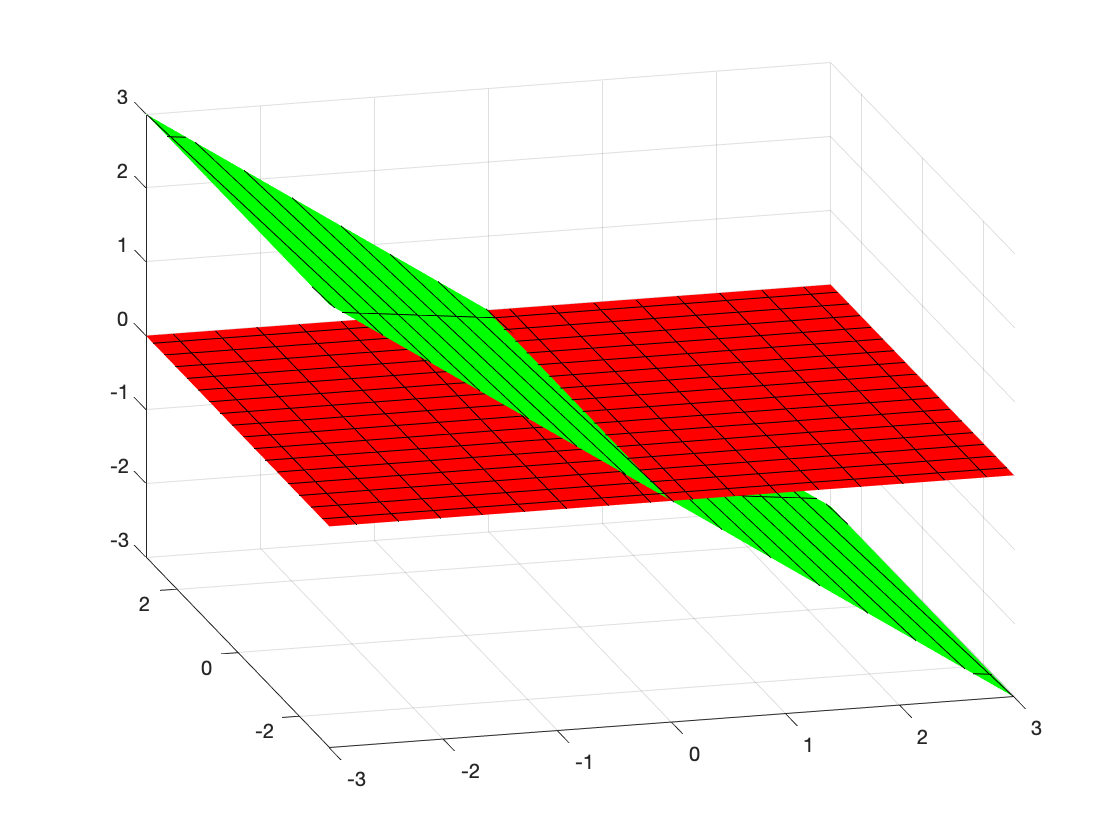

figure
s=linspace(-3.5,3.5,20);
t=linspace(-3.5,3.5,20);
[S,T]=meshgrid(s,t);
X=S-T;
Y=2*S+13*T;
Z=-S+T;
surf(X,Y,Z,'FaceColor','g')
hold on
X2=S;
Y2=T;
Z2=zeros(size(S));
surf(X2,Y2,Z2,'FaceColor','r')
axis([-3,3,-3,3,-3,3])
hold off
view(-15,24)

Clear evidence that they are not the same column space.